## Задание 2. Сэмплирование

### ***Сэмплирование sinus cardinalis***

Исследуем теорему Найквиста-Шеннона-Котельникова на двух примерах...

Но так как эта теорема должна работать на бесконечной числовой оси, которую мы ей не в силах обеспечить, то будем работать  на** большом промежутке**, но показывать малый...

Задайтесь параметром b и рассмотрите функцию y(t) = sinc(bt). 

**Выполняем все шаги из предыдущего пункта**

**Задаём начальные параметры**

b = 3; counter = 18;
t = linspace(-100, 100, 8000);
original_delta = t(2) - t(1)

original_delta = 0.0250

y = sinc(b*t);

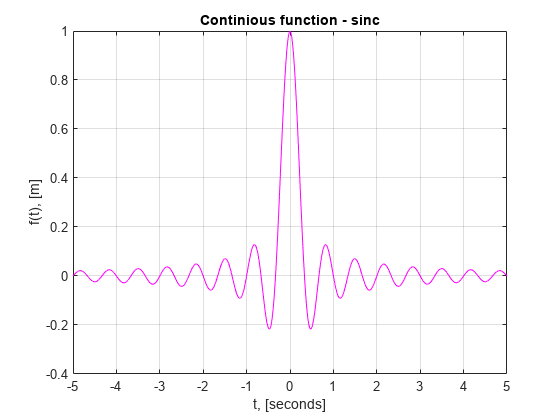


figure;
plot(t, y, 'magenta');
grid on
xlabel('t, [seconds]');
xlim([-5,5])
title("Continious function - sinс")
ylabel('f(t), [m]');
hold off;

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Посмотрми на сэмплированный вариант указанной функции: рассмотрим разреженный вариант массива времени и соответствующий ему массив значений. **на [-20 ; 20]**

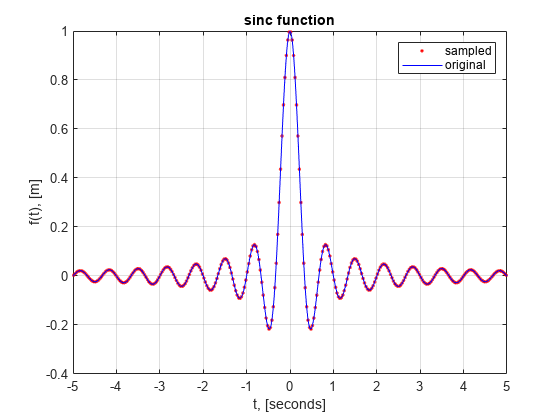

t_sampled = linspace(-100, 100, 6000);
y_sampled = sinc(b*t_sampled);

figure;
plot(t_sampled, y_sampled, 'r.');
xlim([-5,5])
hold on;
plot(t, y, 'b');
alpha(.5)
grid on
xlabel('t, [seconds]');
title("sinc function")
ylabel('f(t), [m]');
hold off;
legend('sampled','original')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Применим интерполяционную формулу 


$$f\left(t\right)=\sum_{n=-\infty }^{+\infty } f\left(t_n \right)\cdot \textrm{sinc}\left(2B\left(t-t_n \right)\right),\;\;t_n =\frac{n}{2B}$$


 Должны получиться новые массивы времени и значений – той же размерности, что и исходные. Постройте график восстановленной функции поверх исходной.

Приблизим покрупнее результат, чтобы понять, что мы смогли действительно восстановить исходную функцию в хорошем приближении

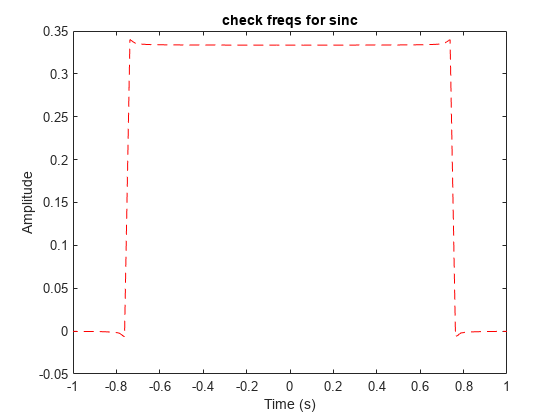

NN = size(t); N = NN(end); V = 200;
v = linspace(-V,V, N); 

DFT = zeros(size(v));
for i = 1:length(v)
    DFT(i) = trapz(t, y .* exp(-1j * 2 * pi * v(i) * t));
end

figure;
plot(t, real(DFT), '--r');
title('check freqs for sinc');
xlim([-1,1])
xlabel('Time (s)');
ylabel('Amplitude');

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

### Испытание 1

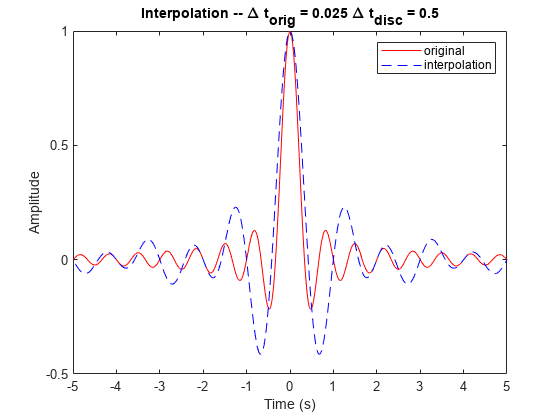

B =  1;
delta_n = (1 /(2*B));
t_n = -1000:delta_n:1000;
f_n = sinc(b*t_n);
f = zeros(size(t)); 
eps = 0.001;
for i = 1:length(t)
    f(i) = sum(f_n .* sinc(2*B*(t(i) - t_n) + eps));
end
figure;
plot(t, y, 'red');
xlim([-5,5])
hold on
plot(t, f, '--b');
title("Interpolation -- " + "\Delta t_{orig} = " + round(original_delta,5) + " \Delta t_{disc} = " + round(delta_n, 5));
xlabel('Time (s)');
xlim([-5,5])
ylabel('Amplitude');
legend('original','interpolation')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

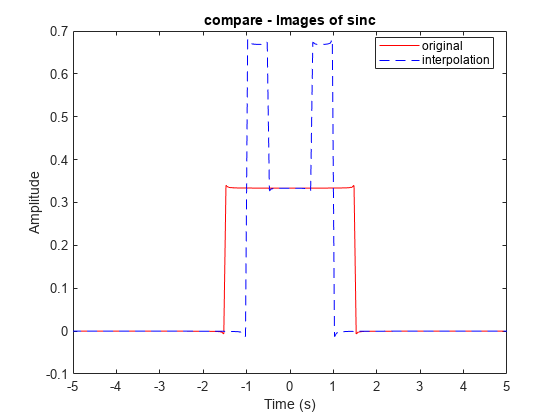


DFT1 = zeros(size(v)); DFT2 = zeros(size(v));
for i = 1:length(v)
    DFT1(i) = trapz(t, y .* exp(-1j * 2 * pi * v(i) * t));
    DFT2(i) = trapz(t, f .* exp(-1j * 2 * pi * v(i) * t));
end

figure;
plot(v, real(DFT1), 'r');
hold on
plot(v, real(DFT2), '--b');
xlim([-5,5])
title('compare - Images of sinc');
xlabel('Time (s)');
ylabel('Amplitude');
lgd = legend('original','interpolation');
legend('Location','best');

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

### Испытание 2

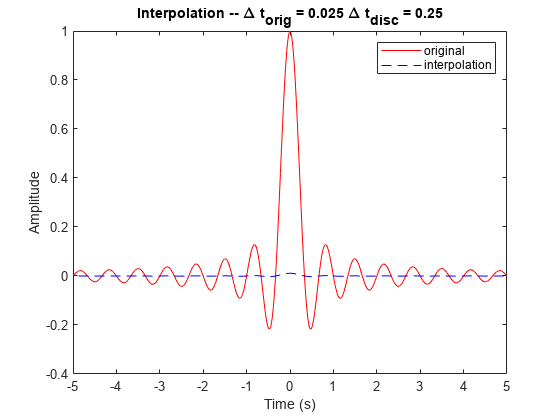

B =  2;
delta_n = (1 /(2*B));
t_n = -1000:delta_n:1000;
f_n = sinc(b*t_n); 
f = zeros(size(t)); 

for i = 1:length(t)
    f(i) = 1/sqrt(length(t)) * sum(f_n .* sinc(2*B*(t(i) - t_n)));
end


figure;
plot(t, y, 'red');
xlim([-5,5])
hold on
plot(t, f, '--b');
title("Interpolation -- " + "\Delta t_{orig} = " + round(original_delta,5) + " \Delta t_{disc} = " + round(delta_n, 5));
xlabel('Time (s)');
xlim([-5,5])
ylabel('Amplitude');
legend('original','interpolation')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

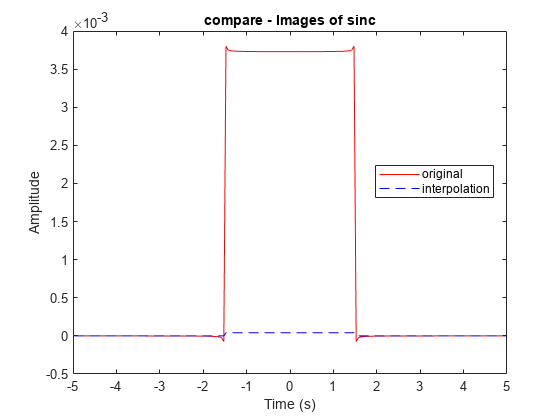


DFT1 = zeros(size(v)); DFT2 = zeros(size(v));
for i = 1:length(v)
    DFT1(i) = 1/sqrt(length(t)) * trapz(t, y .* exp(-1j * 2 * pi * v(i) * t));
    DFT2(i) = 1/sqrt(length(t)) * trapz(t, f .* exp(-1j * 2 * pi * v(i) * t));
end

figure;
plot(v, real(DFT1), 'r');
hold on
plot(v, real(DFT2), '--b');
xlim([-5,5])
title('compare - Images of sinc');
xlabel('Time (s)');
ylabel('Amplitude');
lgd = legend('original','interpolation');
legend('Location','best');

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

### Испытание 3

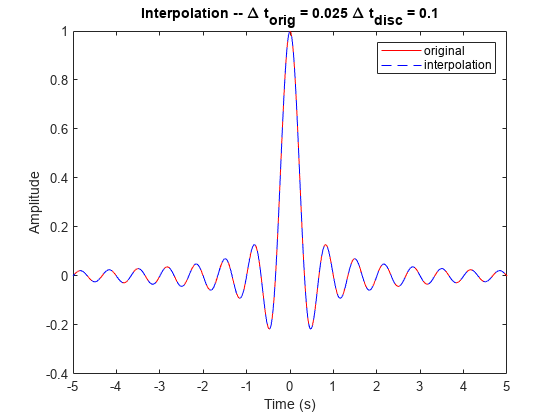

B =  5;
delta_n = (1 /(2*B));
t_n = -1000:delta_n:1000;
f_n = sinc(b*t_n);
f = zeros(size(t)); 

for i = 1:length(t)
    f(i) = sum(f_n .* sinc(2*B*(t(i) - t_n)));
end
figure;
plot(t, y, 'red');
xlim([-5,5])
hold on
plot(t, f, '--b');
title("Interpolation -- " + "\Delta t_{orig} = " + round(original_delta,5) + " \Delta t_{disc} = " + round(delta_n, 5));
xlabel('Time (s)');
ylabel('Amplitude');
legend('original','interpolation')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

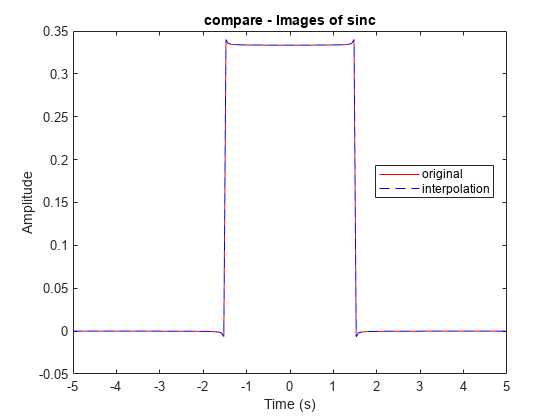


DFT1 = zeros(size(v)); DFT2 = zeros(size(v));
for i = 1:length(v)
    DFT1(i) = trapz(t, y .* exp(-1j * 2 * pi * v(i) * t));
    DFT2(i) = trapz(t, f .* exp(-1j * 2 * pi * v(i) * t));
end

figure;
plot(v, real(DFT1), 'r');
hold on
plot(v, real(DFT2), '--b');
xlim([-5,5])
title('compare - Images of sinc');
xlabel('Time (s)');
ylabel('Amplitude');
lgd = legend('original','interpolation');
legend('Location','best');

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

### Испытание 4

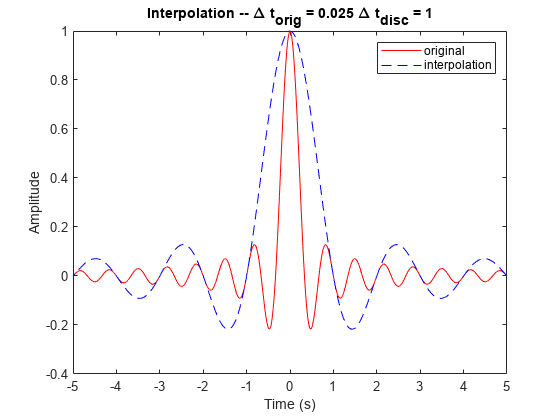

B =  0.5;
delta_n = (1 /(2*B));
t_n = -1000:delta_n:1000;
f_n = sinc(b*t_n);
f = zeros(size(t)); 

for i = 1:length(t)
    f(i) = sum(f_n .* sinc(2*B*(t(i) - t_n)));
end
figure;
plot(t, y, 'red');
xlim([-5,5])
hold on
plot(t, f, '--b');
title("Interpolation -- " + "\Delta t_{orig} = " + round(original_delta,5) + " \Delta t_{disc} = " + round(delta_n, 5));
xlabel('Time (s)');
ylabel('Amplitude');
legend('original','interpolation')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

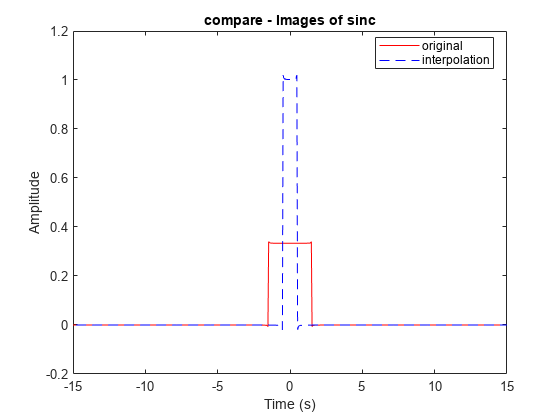



DFT1 = zeros(size(v)); DFT2 = zeros(size(v));
for i = 1:length(v)
    DFT1(i) = trapz(t, y .* exp(-1j * 2 * pi * v(i) * t));
    DFT2(i) = trapz(t, f .* exp(-1j * 2 * pi * v(i) * t));
end

figure;
plot(v, real(DFT1), 'r');
hold on
plot(v, real(DFT2), '--b');
xlim([-15,15])
title('compare - Images of sinc');
xlabel('Time (s)');
ylabel('Amplitude');
lgd = legend('original','interpolation');
legend('Location','best');

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "2_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

**Дополнительно, для каждой величины шага дискретизации постройте Фурье-образ исходного и восстановленного сигналов. **

**Дайте объяснение увиденному, сделайте выводы**